clear all
close all
clc

## Loading In Audio

handel = load("handel.mat")

handel = struct with fields:
     y: [73113×1 double]
    Fs: 8192


laughter = load("laughter.mat")

laughter = struct with fields:
     y: [52634×1 double]
    Fs: 8192


handel.y = handel.y(linspace(1,handel.Fs*5,handel.Fs*5));
laughter.y = laughter.y(linspace(1,laughter.Fs*5,laughter.Fs*5));

## Creating our 2kHz lowpass filter

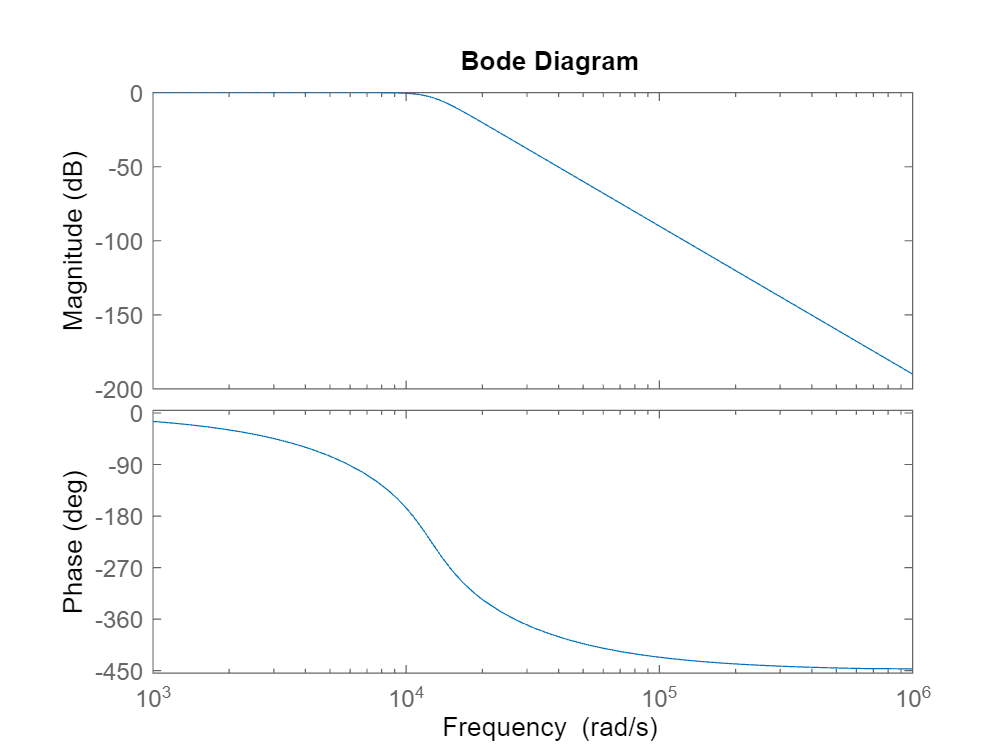

fc = 2000; % Hz Cutoff Frequency
[num, den] = butter(5,2*pi*fc,"low",'s');
H_butter = tf(num,den);
clear num den
bodeplot(H_butter)

## Normalizing the signals to 0,2 and upsampling to 120 kHz

target_samples = 120000;
samp_rate = target_samples/5;
handel.y = resample((1.+(handel.y./(max(abs(handel.y))))),target_samples,length(handel.y));
laughter.y = resample((1.+(laughter.y./(max(abs(laughter.y))))),target_samples,length(laughter.y));
handel.Fs = samp_rate;
laughter.Fs = samp_rate;